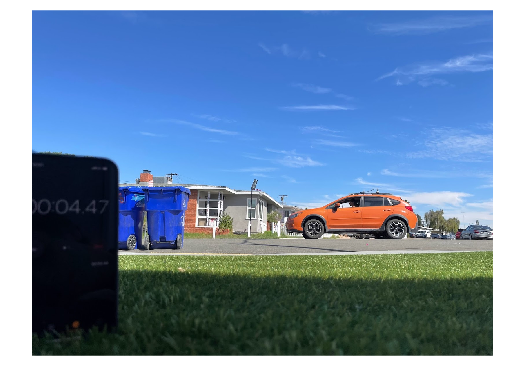

Im3 = imread('Car3.jpg');
imshow(Im3)

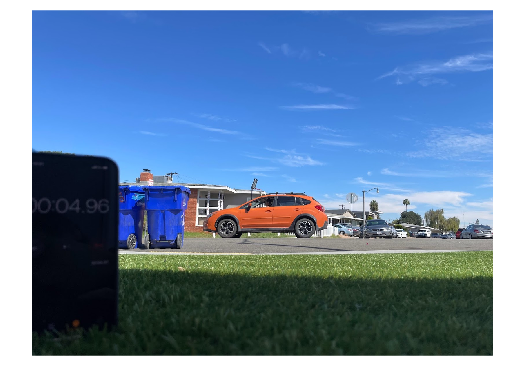

Im4 = imread('Car4.jpg');
imshow(Im4)

carLengthFeet = input('Enter length of car in feet: ') %length of car in feet

carLengthFeet = 15

time3 = input('Enter time in frame 1: ')

time3 = 4.4700

time4 = input('Enter time in frame 2: ')

time4 = 4.9600


timeChange = time4 - time3

timeChange = 0.4900

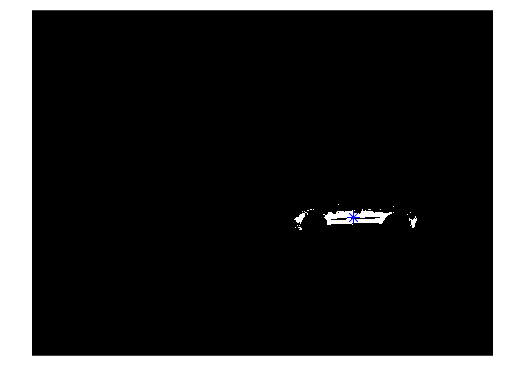


%convert color images to binarized based on color of car
Car3=( ((Im3(:,:,1)>211)&(Im3(:,:,1)<251)) & ((Im3(:,:,2)<116)&(Im3(:,:,2)>76)) & ((Im3(:,:,3)<70)&(Im3(:,:,3)>30)) );
Car4=( ((Im4(:,:,1)>211)&(Im4(:,:,1)<251)) & ((Im4(:,:,2)<116)&(Im4(:,:,2)>76)) & ((Im4(:,:,3)<70)&(Im4(:,:,3)>30)) );

%find centroids of cars in both images
[y, x] = ndgrid(1:size(Car3, 1), 1:size(Car3, 2));
centroid3 = mean([x(logical(Car3)), y(logical(Car3))]);
[y, x] = ndgrid(1:size(Car4, 1), 1:size(Car4, 2));
centroid4 = mean([x(logical(Car4)), y(logical(Car4))]);

%Display images of cars and their centroids
imshow(Car3)
hold on
plot(centroid3(1),centroid3(2),'b*')
hold off

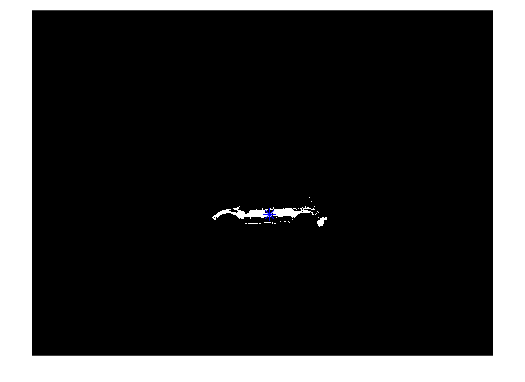

imshow(Car4)
hold on
plot(centroid4(1),centroid4(2),'b*')
hold off


%Find distance between centroids in terms of pixels
distancePix = sqrt( (centroid3(1)-centroid4(1))^2 + (centroid3(2)-centroid4(2))^2 )

distancePix = 287.4747


%find length of car in pixels
[~, columns] = find(Car3);
left3 = min(columns);
right3 = max(columns);
carLengthPix = right3-left3;
lengthFactor = carLengthPix/carLengthFeet;  %Determine factor to convert pixels to feet
distanceFeet = distance/lengthFactor        %Translate distance travelled to feet

distanceFeet = 10.2426


%determine speed
speedFPS = distanceFeet/timeChange

speedFPS = 20.9032

speedMPH = speedFPS*0.681818

speedMPH = 14.2522